# Visualise conserved moieties in dopaminergic neuronal metabolism

## Author(s): Ronan M.T. Fleming, School of Medicine, University of Galway

## Reviewer(s): 

## INTRODUCTION

Given a set of conserved moieties, this tutorial generates metabolic maps corresponding to different conserved moieties.

These tutorials should generally be used in the following order:

1. Initialise and set the paths to inputs and outputs

COBRA.tutorials/driver_initConservedMoietyPaths.mlx   

2. Build an atom transition graph

tutorial_buildAtomTransitionMultigraph.mlx

3. Identify conserved moieties, given an atom transition graph                                               

tutorial_identifyConservedMoieties.mlx

4. Analyse the output of #3

tutorial_analyseConservedMoieties.mlx 

5. Prepare for visualisation of individual conserved moieties (beta)      

tutorial_visualiseConservedMoieties.mlx

tutorial_initConservedMoietyPaths

modelName = 'DAS'

projectDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties'

dataDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/data/models/'

softwareDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/software/'

visDataDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/data/visualisation/'

resultsDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/results/DAS_ConservedMoieties/'

rxnfileDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/data/mini-ctf/rxns/atomMapped'

% if ~recompute
%     load([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])
%     return
% end

Load the dopaminergic neuronal metabolic model

load([dataDir modelName '.mat'])

Identify the stoichiometrically consistent subset of the model

massBalanceCheck=1;
printLevel=1;
[SConsistentMetBool, SConsistentRxnBool, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model]...
    = findStoichConsistentSubset(model,massBalanceCheck,printLevel);

--- findStoichConsistentSubset START ----
--- Summary of stoichiometric consistency ----
    11	    11	 totals.
     0	     7	 heuristically external.
    11	     4	 heuristically internal:
    11	     4	 ... of which are stoichiometrically consistent.
     0	     0	 ... of which are stoichiometrically inconsistent.
     0	     0	 ... of which are of unknown consistency.
---
     0	     0	 heuristically internal and stoichiometrically inconsistent or unknown consistency.
     0	     0	 ... of which are elementally imbalanced (inclusively involved metabolite).
     0	     0	 ... of which are elementally imbalanced (exclusively involved metabolite).
    11	     4	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----


### Metabolite connectity

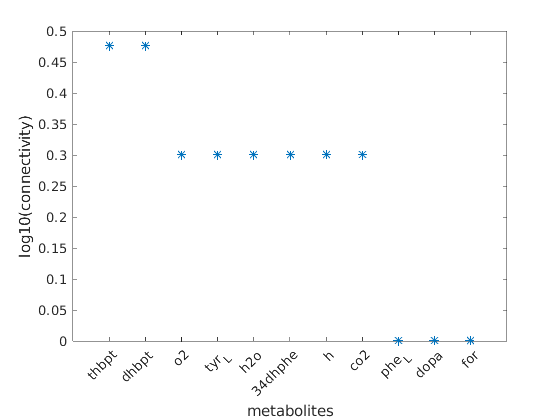

param.n=20;
[rankMetConnectivity,rankMetInd,rankConnectivity] = rankMetabolicConnectivity(model,param);

### Load atomically resolved models & conserved moiety analysis

Load the atomically resolved models derived from identifyConservedMoieties.m

if 0
    load([resultsDir 'iDopaMoieties_noChecks.mat'])
else
    load([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])
end

### Transitive moiety, of sufficient mass, with moderate incidence

isTransititiveMoiety= strcmp('Transitive',moietyTypes);
isModerateIncidence = moietyIncidence>=10 & moietyIncidence<=100;
isSufficientMass = moietyMasses > 2;
isSufficientMinimalMassFraction = minimalMassFraction > 0.1;
interestingMoiety = isTransititiveMoiety & isModerateIncidence & isSufficientMass & isSufficientMinimalMassFraction;
C = cell(nnz(interestingMoiety),9);
n=1;
for i=1:size(arm.L,1)
    if interestingMoiety(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moiety_formula','mass','Minimal_mass_metabolite','Name','Formula','Mass_fraction'};
size(T,1)

ans = 0

disp(T)

### Recon3Map

Import Recon3Map

if ~exist('Recon3xml','var')   
    [Recon3xml, Recon3map] = transformXML2Map([visDataDir 'reconMap3d_allin.xml']);
end
if 0
    transformMap2XML(Recon3xml,Recon3map,[resultsDir 'Recon3map.xml']);
end

### Compare the reactions in the specified metabolic model and Recon3Map

The function `checkCDerrors` gives four outputs summarising all possible discrepancies between model and map.

printLevel=0;
[diffReactions, diffMetabolites, diffReversibility, diffFormula] = checkCDerrors(Recon3map, model,printLevel);

Four outputs are obtained from this function:

"`diffReactions`" summarises present and absent reactions between model and map.

Display the internal reactions in the model that are not present in the map.

bool=ismember(diffReactions.extraRxnModel,model.rxns(model.SConsistentRxnBool));
nnz(bool)

ans = 4

disp(diffReactions.extraRxnModel(bool))

    {'R1'}
    {'R2'}
    {'R3'}
    {'R4'}



"`diffMetabolites`" summarises present and absent metabolites. 

***NOTE!**** Note that having more metabolites and reactions in the COBRA model is normal since the model can contain more elements than the map. On the other hand, the map should only contain elements present in the model.*

 "`diffReversibility`" summarises discrepancies in defining the reversibility of reactions.

The last output "`diffFormula"` summarises discrepancies in reactions formulae (kinetic rates) and also lists duplicated reactions.

### Create a map of the model

Remove some reactions from the map

rxnRemoveList = diffReactions.extraRxnsMap;

Remove non-dopaminergic neuronal reactions from the map

[modelNameXml,modelNameMap] = removeMapReactions(Recon3xml, Recon3map,rxnRemoveList);

Remove pathway labels from the map

specRemoveType='UNKNOWN';
specRemoveList=[];
printLevel=0;
[modelNameXml,modelNameMap,specNotInMap] = removeMapSpecies(modelNameXml,modelNameMap,specRemoveList,specRemoveType,printLevel);

Remove highly connected metabolites from the map

specRemoveList={'h[c]';'h[l]';'h[e]';'h[r]';'h2o[c]';'h2o[l]';'h20[e]';'pi[c]';'adp[c]';'nadph[c]';'nadh[c]';'nadph[m]';'nadh[m]'};
[xmlStruct,map,specNotInMap] = removeMapSpeciesOnly(modelNameXml,modelNameMap,specRemoveList,specRemoveType,printLevel);

Export the model map

transformMap2XML(modelNameXml,modelNameMap,[resultsDir modelName '_CD.xml']);

Elapsed time is 0.030606 seconds.


### Nicotinate moiety

ind = 9;% Nicotinate moiety
mBool=arm.L(min(ind,size(arm.L,1)),:)~=0;
nnz(mBool)

ans = 5

rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
nnz(rBool)

ans = 6

Metabolites

bool=mBool;
C = cell(nnz(bool),5);
n=1;
for i=1:size(model.S,1)
    if bool(i)
        C(n,1:5) = {i,model.mets{i},model.metNames{i},model.metFormulas{i},metMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','met','name','formula','mass'};
disp(T)

    index        met           name          formula        mass 
    _____    ___________    ___________    ____________    ______

      7      {'34dhphe'}    {'34dhphe'}    {'C9H11NO4'}    197.07
      4      {'tyr_L'  }    {'tyr_L'  }    {'C9H11NO3'}    181.07
      9      {'dopa'   }    {'dopa'   }    {'C8H12NO2'}    154.09
      3      {'o2'     }    {'o2'     }    {'O2'      }     31.99
      6      {'h2o'    }    {'h2o'    }    {'H2O'     }    18.011



Reactions

formulas = printRxnFormula(model, model.rxns(rBool));

R1	phe_L + thbpt + o2 	->	tyr_L + dhbpt + h2o 
R2	thbpt + o2 + tyr_L 	->	dhbpt + h2o + 34dhphe 
R3	34dhphe + h 	->	dopa + co2 
EX_o2	o2 	<=>	
EX_h2o	h2o 	->	
EX_dopa	dopa 	->	


### Map of nicotinate subnetwork

This code is specific to the dopaminergic neuronal metabolic model. Export the dopaminergic neuronal model as an sbml file

if 0
    nicotinateRxnRemoveList=model.rxns(~rBool);
    [iDopaNicotinateXml,iDopaNicotinateMap] = removeMapReactions(iDopaXml,iDopaMap,nicotinateRxnRemoveList);
    transformMap2XML(iDopaNicotinateXml,iDopaNicotinateMap,[resultsDir modelName '_Nicotinate_CD.xml']);
    outmodel = writeCbModel(model, 'format','sbml','fileName', [resultsDir 'iDopaNeuro_SBML.xml']);
end

## Generate a set of submodels of the interesting moieties

Get abbreviations, without compartments for each metabolite in the model, then generate a results directory for each interesting moiety

[compartments, uniqueCompartments, minimalMassMetaboliteAbbr, uniqueAbbr]= getCompartment(minimalMassMetabolite);
extractSubnetwork=1;
matFile=0;
sbmlFile=1;
moietyData=1;
CDFile=0;
n=1;
for i=1:size(arm.L,1)
    if interestingMoiety(i)
        metSampleName = minimalMassMetaboliteAbbr{i};
        disp(metSampleName)
        [SUCCESS,MESSAGE,MESSAGEID] = mkdir(resultsDir,metSampleName);
        cd([resultsDir filesep metSampleName])
        mBool = arm.L(i,:)~=0;
        rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
        if extractSubnetwork
            modelNameInterestingSubModel{n,1} = extractSubNetwork(model, model.rxns(rBool), model.mets(mBool), 1);
        end
        mBoolModel = ismember(model.mets,modelNameInterestingSubModel{n,1}.mets);
        modelNameInterestingSubModel{n,2}=i;
        modelNameInterestingSubModel{n,3}=minimalMassMetabolite{i};
        
        if matFile
            outmodel = writeCbModel(modelNameInterestingSubModel{n,1}, 'format','mat','fileName', [resultsDir metSampleName filesep modelName '_' metSampleName '.mat']);
        end
                
        if sbmlFile
            outmodel = writeCbModel(modelNameInterestingSubModel{n,1}, 'format','sbml','fileName', [resultsDir metSampleName filesep modelName '_' metSampleName '_SBML.xml']);
        end
        
        if moietyData
            
            moietyIncidence = arm.L(modelNameInterestingSubModel{n,2},ismember(model.mets,modelNameInterestingSubModel{n,1}.mets))';
            
            fileName = [resultsDir metSampleName filesep modelName '_' metSampleName '_moietyData.txt'];
            param.name = [modelName '_' metSampleName 'MoietySubnetwork'];
            param.description = [modelName '_' metSampleName ' moiety incidence'];
            param.color.minValue = -1;
            param.color.minColor = '#FF0000';
            param.color.zeroValue = 0;
            param.color.zeroColor = '#FFFFFF';
            param.color.maxValue =  full(max(moietyIncidence));
            param.color.maxColor = '#87CEFA';
            writeNewtExperiment(modelNameInterestingSubModel{n,1},moietyIncidence,metSampleName,fileName,param);
        end
        
        if CDFile
            [modelNameInterestingXml{n},modelNameInterestingMap{n},modelNameRxnNotInMap{n}] = removeMapReactions(modelNameXml,modelNameMap,model.rxns(~rBool));
            transformMap2XML(modelNameInterestingXml{n},modelNameInterestingMap{n},[resultsDir metSampleName filesep modelName '_' metSampleName '_CD.xml']);
        end
        n=n+1;
        cd('../')
    end
end

## *Acknowledgments*

Co-funded by the European Union's Horizon Europe Framework Programme (101080997)

## REFERENCES

- Ghaderi, S., Haraldsdóttir, H. S., Ahookhosh, M., Arreckx, S., & Fleming, R. M. T. (2020). Structural conserved moiety splitting of a stoichiometric matrix. Journal of Theoretical Biology, 499, 110276. [https://doi.org/10.1016/j.jtbi.2020.110276](https://doi.org/10.1016/j.jtbi.2020.110276)

- Rahou, H., Haraldsdóttir, H. S., Martinelli, F., Thiele, I., & Fleming, R. M. T. (2026). Characterisation of conserved and reacting moieties in chemical reaction networks. Journal of Theoretical Biology, 112348. [https://doi.org/10.1016/j.jtbi.2025.112348](https://doi.org/10.1016/j.jtbi.2025.112348) 